# Final Project

## Hand Trajectories

Behavioral: Two plots of hand position per condition over time. One of these plots should be for the curved reaches and the other should be for the straight reaches. Each direction condition will be plotted in a different color

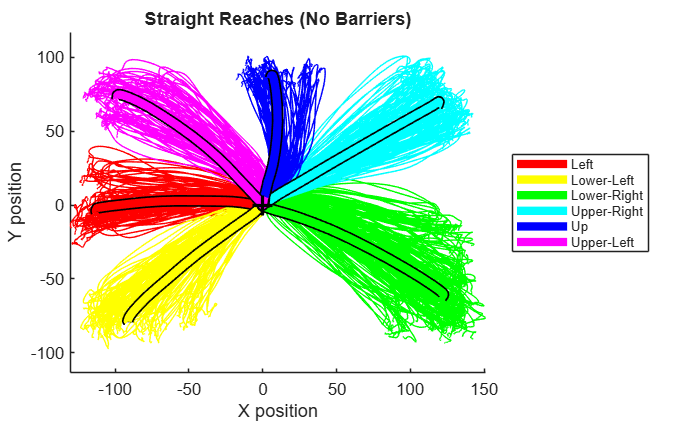

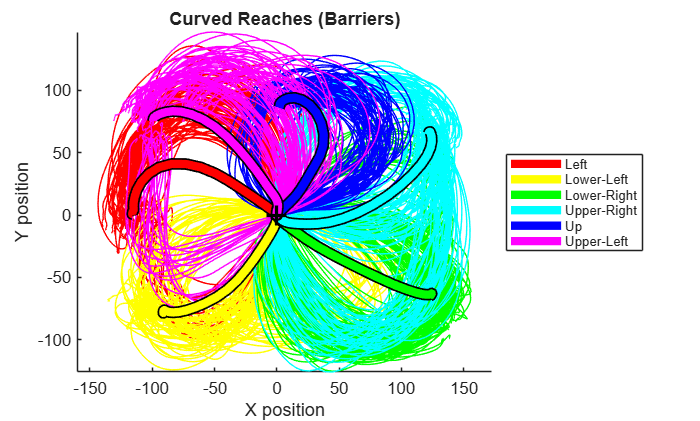

plotHandTrajectories(R);

This visualization plots the hand position of the monkey throughout the trial, divided by condition (curved vs. straight) and colored by direction. The thin lines represent individual trial trajectories, whereas the bold thick lines are the trial averaged means. There are several features of the data that are worth noting. First, the data supports our reach direction clustering as a relevant task feature, as the individual trajectories naturally cluster into 6 distinct directions. Second, the two conditions produce very different kinematic trajectories. The curved reaches are noticeably more variable, reflecting the need to avoid the obstacles. On the other hand, the no barriers condition produces relatively straight and radially organized paths to their targets. Note that the mean trajectories have been time normalized. So timing differences are smoothed over for the sake of visualization.

## Raster Plots

Neural: Raster plot for an example M1 neuron with trials sorted by reach direction and aligned to the movement onset

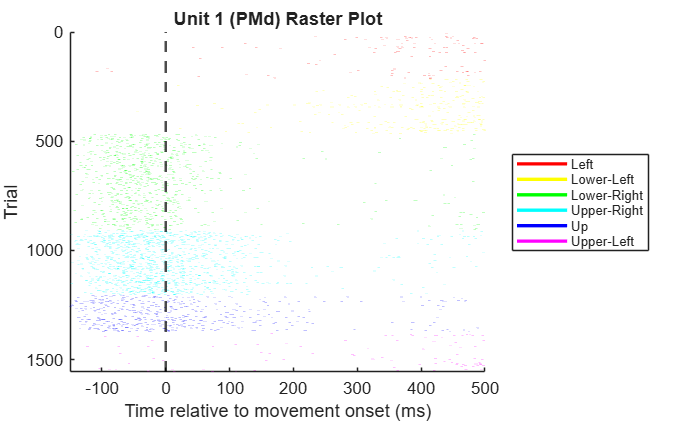

plotRaster(R, 1, 150, 500); % inputs in order: dataset, unit number, pre movement window(ms), post movement window(ms).

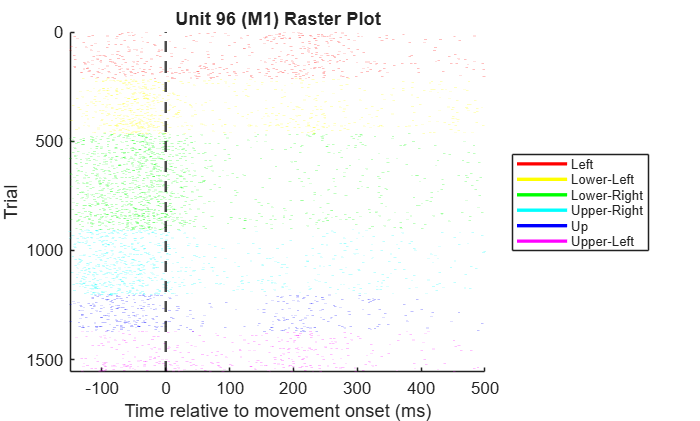

plotRaster(R, 96, 150, 500);

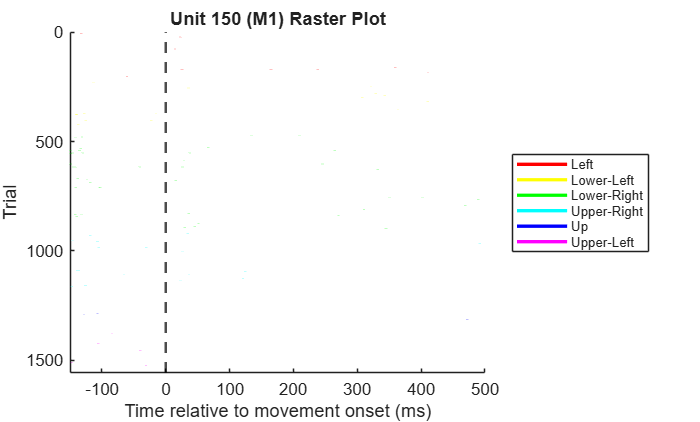

plotRaster(R, 150, 150, 500);

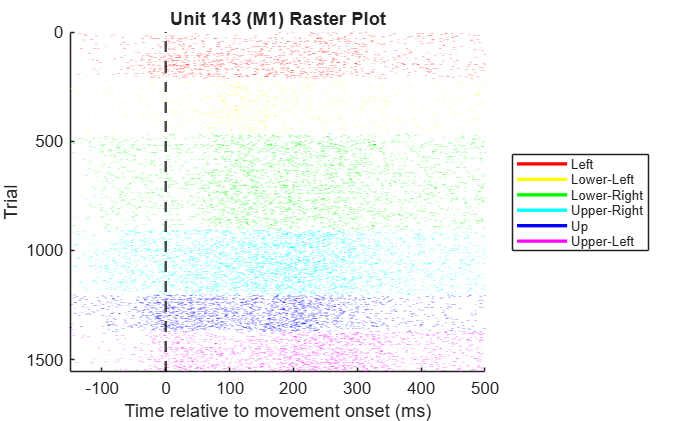

plotRaster(R, 143, 150, 500);

Here we've plotted several example raster plots of neural activity centered around movement onset during the task. This type of visualization allows us to characterize the neuron's directional tuning, amplitude of response, and temporal profile. We chose 4 neurons that show the heterogeneity of potential responses. Unit 1 responds predominately to reaches spanning lower right to up in the task. Notably, the peak response occurs before movement onset, which may be indicative of preparatory activity. The firing of this neuron seems to fade as the trial progresses. Unit 96 looks to have a much broader tuning profile, as it responds to nearly all reach directions, albeit a few more strongly. Similarly to neuron 1, firing seems to slow after movement onset for most of the directions, except for left/up, which has an additional response during movement. Unit 150 is not tuned to any of the directions, only sparsely firing throughout the trials with no apparent structure. Unit 143 also shows a very broad tuning profile, but it has different temporal characteristics. Activity ramps during the delay period, but peaks and maintains throughout the movement epoch. This all goes to show the variability in response in both M1 and PMd, units in both regions show different firing rates, modulation depths, and tuning.

## Peri-Stimulus Time Histograms

Neural: PSTH for the same example M1 neuron averaged by reach direction condition and aligned to movement onset

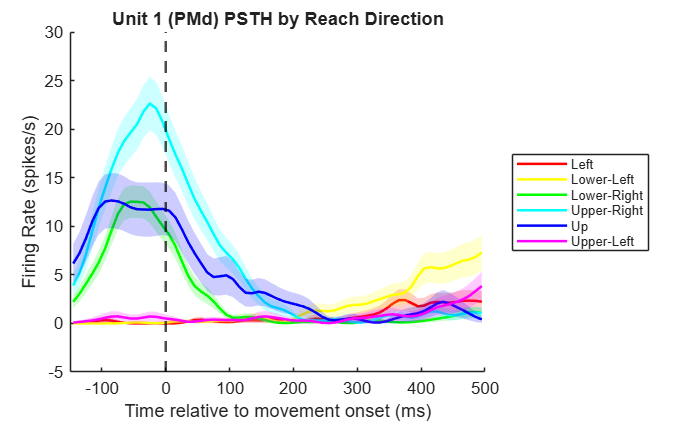

plotPSTH(R, 1, 150, 500, 10); % inputs in order: data set, unit number, pre movement window(ms), post movement window(ms), bin size(ms)

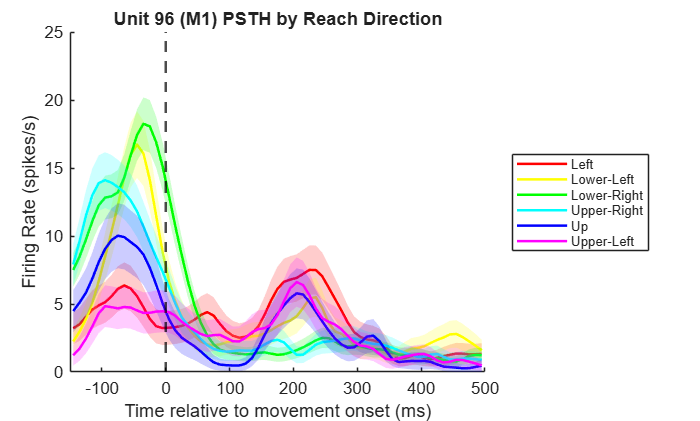

plotPSTH(R, 96, 150, 500, 10);

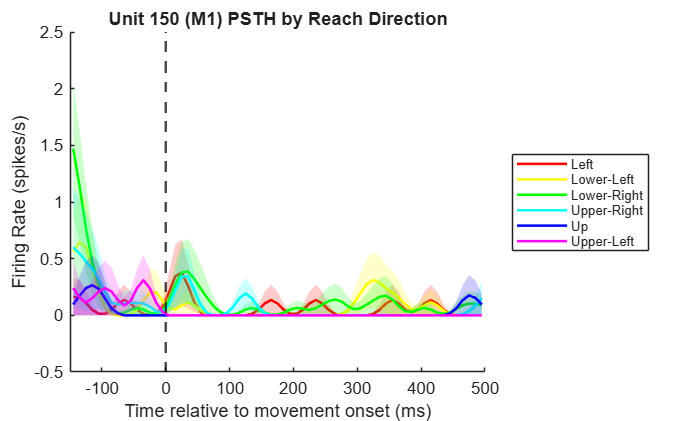

plotPSTH(R, 150, 150, 500, 10);

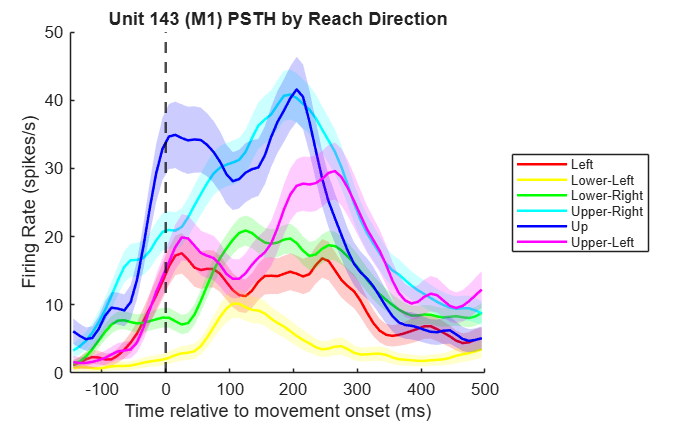

plotPSTH(R, 143, 150, 500, 10);

Here we have several Peri-Stimulus/Event Time Histograms for motor neurons aligned to movement onset. This is another type of neural data visualization that can show trends/responses across time as well as the preferred conditions where a neuron exhibits its optimal firing responseNeuron 1: Has clear directional tuning to up through lower right, peaking before movement onset and decaying throughout the movement epoch. Neuron 96: Has relatively strong directional tuning to most directions, with a weaker response to left and upper left. Activity peaks before movement onset and decays at a much faster rate than previously seen with neuron 1. There does seem to be an additional response at 200 ms after movement onset, which could be representative of a movement parameter or something that occurred in the trial. Neuron 150: Shows no clear directional tuning for this neuron. It's firing rate is generally flat and noisy. Neuron 143: Has broad tuning to nearly all directions. Activity ramps up during the delay period but peaks later on in the movement period around 200 ms in. Again these visualizations display the heterogeneity of response found at the level of individual units, not all M1 units are exclusively active during the movement phase and not all PMd neurons during the delay phase. Neurons in both regions can be active during both phases of the task. In comparing the PSTHs and raster plots, it often can be easier to visualize the direction that elicits the highest firing response given how the data is represented.

## Tuning Curve Plot

Neural: Tuning curve plot for each neuron overlaid, with the mean in bold to show tuning across the population

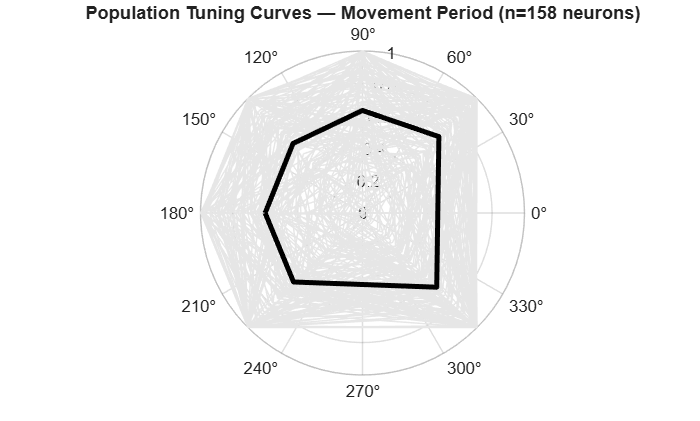

plotTuningCurve(R);

The population shows broad heterogeneity in response to all directions across both brain regions. It appears that individual neurons are tuned to all reach direction clusters, and it does not seem like one direction dominates. The population mean curve supports this as it is similarly uniform across the polar plot. This motivates population level analyses, where we can look at what the population encodes. The 6 vertices correspond to the 6 reach direction clusters we divided by. The connecting lines are thus linear interpolations between the groups.

## Behavioral: Curvature Metric

Behavioral: Find a curvature metric (ratio of actual path length to straight line distance between start and end). Plot the distribution of curvature with a bootstrapped confidence interval for curved and straight path conditions. This would be a behavioral verification that the animal actually did the curved paths and not just the straight length ones. 

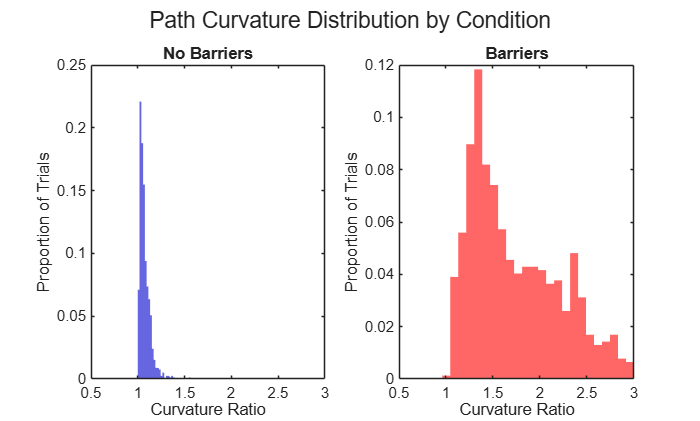

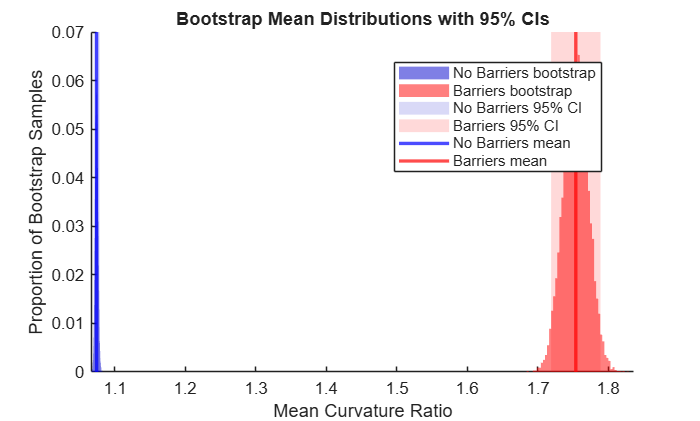

curvatureMetric(R)

The two curvature distributions are distinguishable by the barrier and no barrier conditions. In the barriers condition, we see higher variability. This is expected as the animal needed to take an actual longer path length to complete those trials. The bootstrapped confidence interval further confirms that the curved trials were accurately performed. This non overlapping confidence intervals show us that the dfference between the conditions is consistent across the population. Although we can see from the kinematic trajectory plot earlier the directions the animals took curved reaches, bootstrapping confirms that this behavior is consistent across the population of trials. 

## Behavioral: Peak Hand Velocity

Behavioral: Hand velocity over time split by the curved and straight reaches. Compute peak hand speed during trial, split trials into groups based on curved or straight reaches, compare the means. 

Monte Carlo: shuffle the curved/straight labels, recompute the difference in the means, do this 1,000 times to create a null distribution. P-value would show us if curved and straight reaches have significantly different peak hand speeds. 

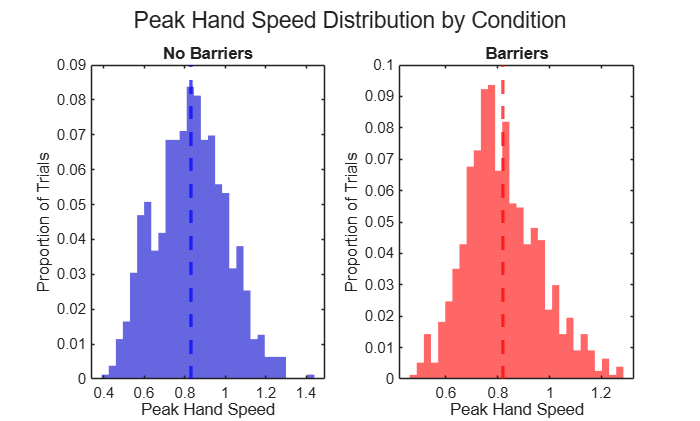

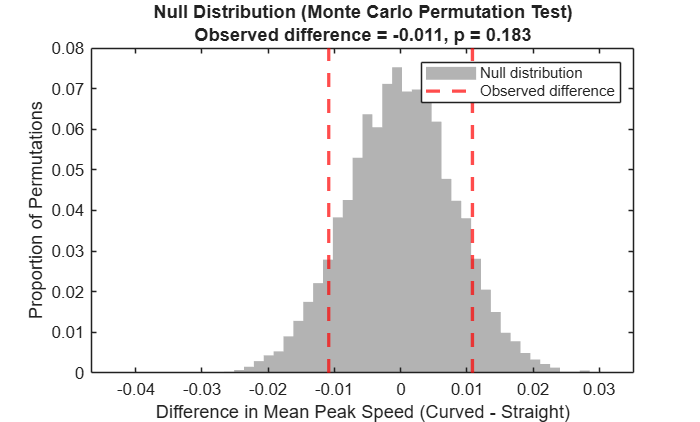

handVelocityMonteCarlo(R)

Between the barrier and no barrier conditions, the peak hand speed distributions overlap significantly. This suggests that the trajectory tasks were performed at the same speeds, reducing the confound that any variability we see in the neural data between the two conditions is due to a difference in velocity. The differences we will see in our later analyses that separate barrier and no barrier conditions will not be due to the animal maybe moving faster in or slower in one condition type. From the Monte Carlo Permutation test, we can see that our p-value is 0.180. This means that we fail to reject the null hypothesis that the no barriers and the barriers condition differ in peak sepeed. 

## Traditional Single-neuron Analysis 

We will use an ROC based Ideal Observer Analysis to compute each M1 neuron’s discriminability between its preferred target location and each of the other targets as a function of angular distance from the preferred, producing a neurometric function per neuron. We will show the average discriminability curve across all neurons as well.

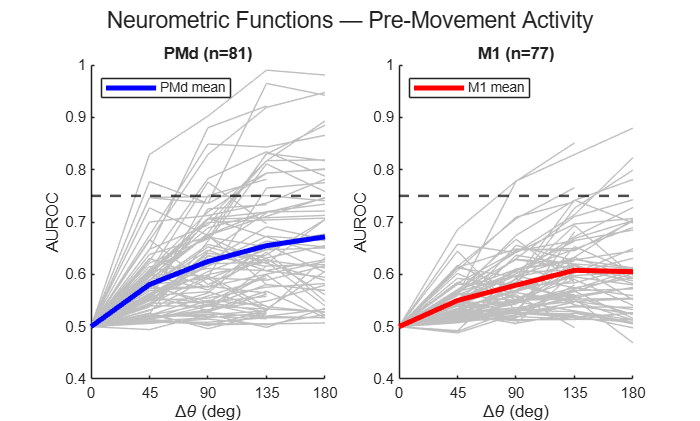

PMd: 18/81 neurons (22%) exceed AUROC 0.75 at any distance
M1:  6/77 neurons (8%) exceed AUROC 0.75 at any distance


plotNeurometricFunctions(R, 250);

Here we have neurometric functions for all 158 motor units, split by brain region, using an ROC ideal observer analysis during the delay period of the task. We plotted each individual neuron's discriminability as a function of angular distance from its preferred reach direction as a transparent gray line, and the average curve for the population as the blue and red lines. The question addressed with this analysis is how well individual neurons can discriminate between their preferred direction and all other directions, and whether that differs across brain region. The neurometric functions reveal that PMd shows greater directional discriminability than M1 units across all angular differences, peaking at around 0.67 at opposing directions, while M1 only peaks at about 0.60. Furthermore, approximately 22% of units in PMd cross our 0.75 threshold compared to only 8% in M1. It's important to note, however, that there is a lot of heterogeneity across the population during preparatory activity. Both brain regions have neurons that are excellent discriminators, and many neurons that cluster around chance. The fact that the mean curve also never passes our threshold suggests that such task features may be better represented in population level activity. This also reveals that while PMd may have more directional discriminability during the delay period, M1 is also able to discriminate. Thus, the functionality of these two brain regions overlap and can be thought of as a spectrum rather than a hard boundary in which PMd is exclusively motor planning and M1 is exclusively motor execution.

## Trial by Trial Variability

We will compute the Fano Factor as a function of time aligned to both the target appearance, movement onset, and go-cue separately for curved and straight reaches to determine how variability evolves across delay and movement and whether this differs for the reach types, considering curved reaches are arguably more complex.

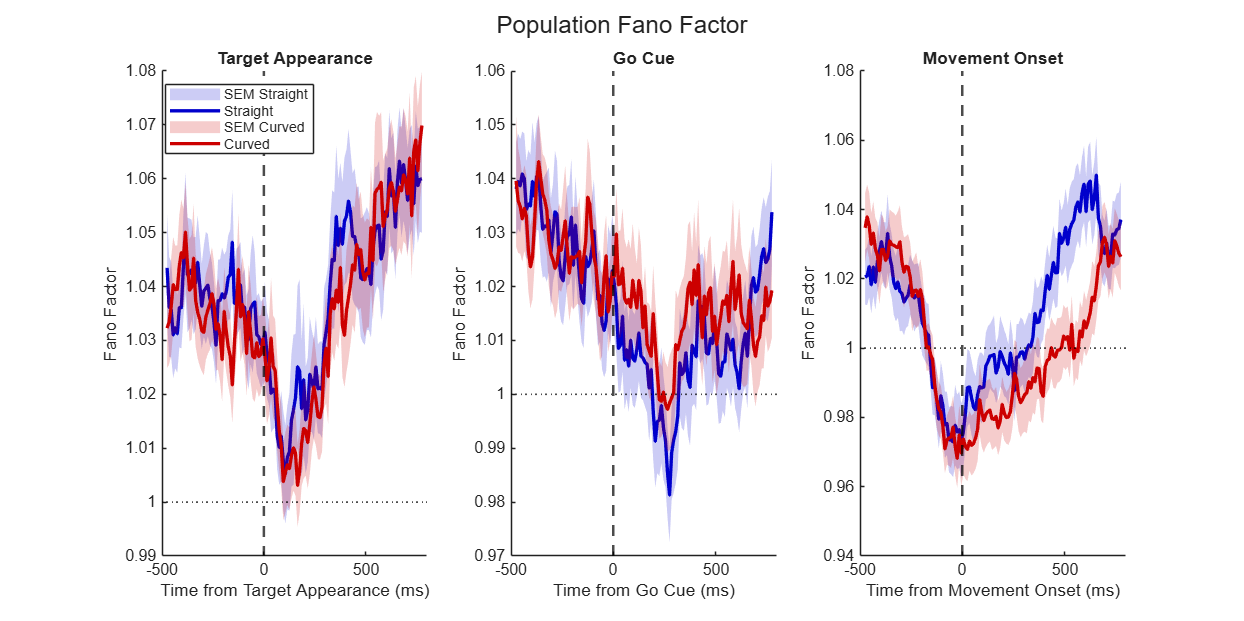

trialToTrialVariability(R)

As we learned in class, the Fano Factor (FF) is used to quantify neural variability, with FF=1 indicating regular firing. The plot shown was averaged At target appearance, the variabilty drops, and steadily rises. The same pattern is shown in the go cue alignment plot. When aligned to the movement onset, we see the straight reaches have a higher variability after movement onset compared to the curved reaches. This could mean that at movement onset, the curved trajectories execute movement in a stereotyped way. These results suggest that straight reaches are more locked to instruction, and curved reaches are more locked to execution. However, it is important to note that these differences in variability are minor. In addition, averaging over the population might minimize the differences in variability we see between the two conditions. 

## Linear Dimensionality Reduction

We will do cross-validated PCA on M1 activity to determine the true low dimensional structure of the neuron's responses, comparing dimensionality under no normalization, z-scoring, and soft normalization.

Firing rates created.


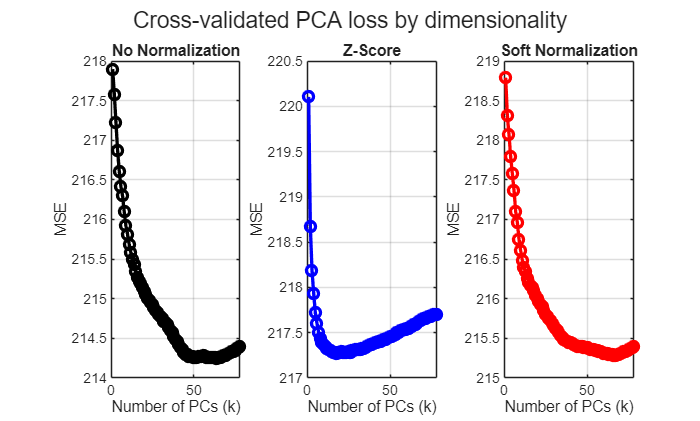

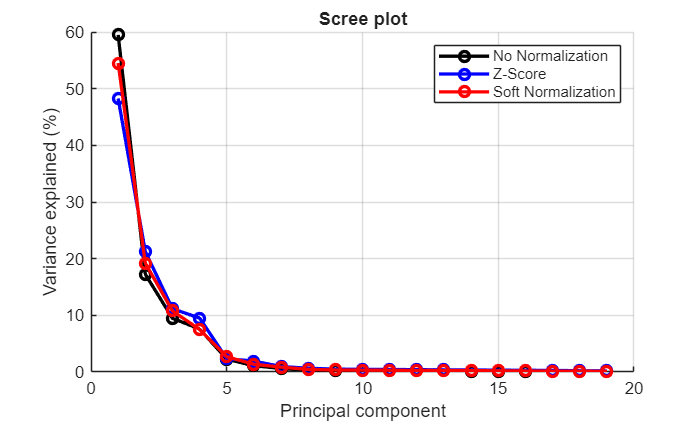

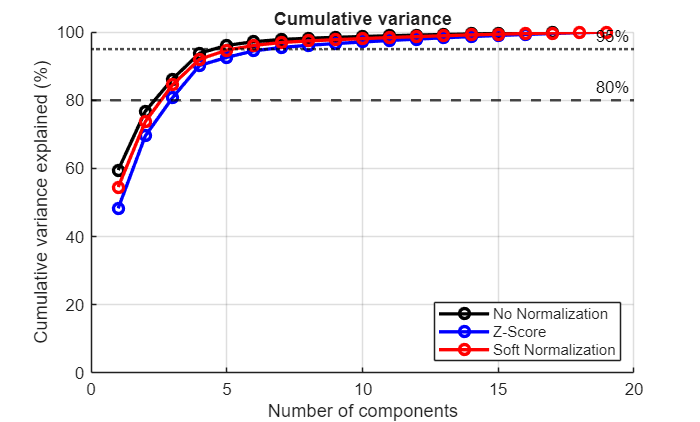

results = linearDimensionalityReduction(R);

The cross-validated PCA plots comparing MSE against the number of PCs show a U-shaped curve between the different normalizations. The sharpest U-shape is in the z-scored plot. As we learned in class, this shape is expected as we increase the number of PCs and the model begins to overfit to the noise. The optimal dimensionality is therefore at the minimum of each of these plots and is around 10 components for the Z-scored plot. This optimal dimensionality varies between the different normalizations with the no normalization and soft normalization having an optimal dimensionality closer to 40 components. In our scree plot, we can see that the first few PCs account for a disproportionate amount of the variance, which is to be expected. The cumulative variance plot also confirms this as the first few components account for the majority of the variance explained. 

## PCA Trajectory Plot

Firing rates created.


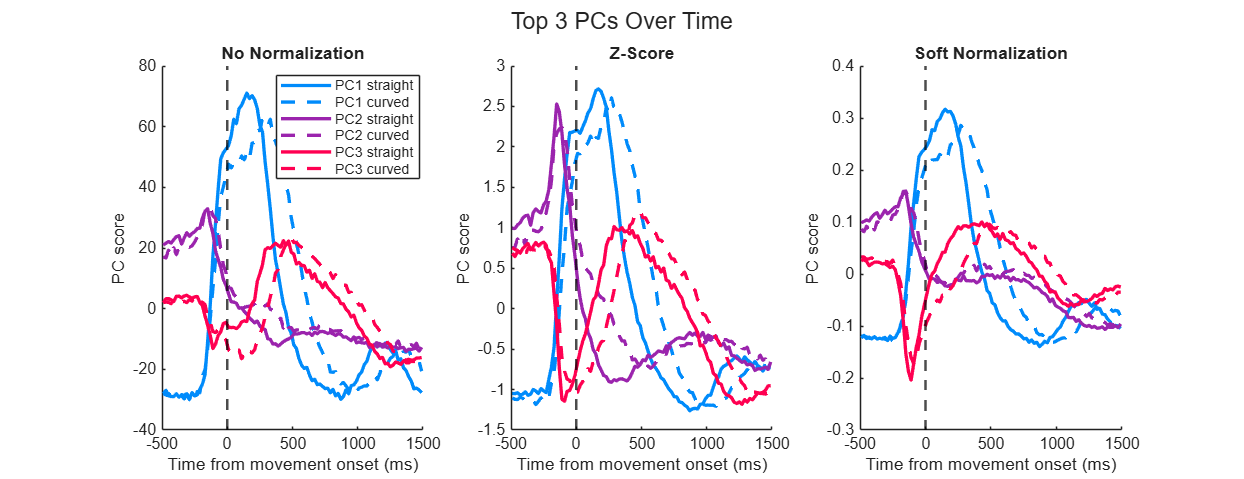

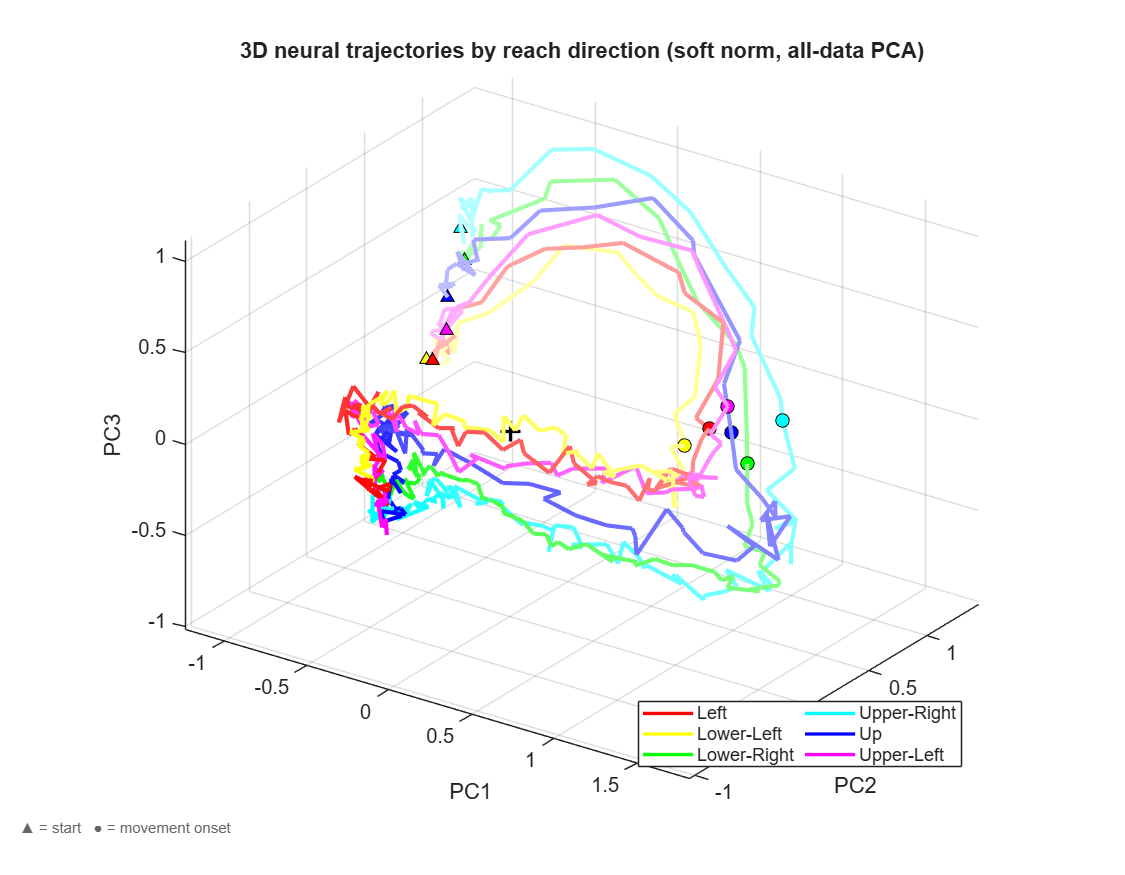

pcaTrajectories(R)

In all of these PCA trajectories, we noticed that PC1 appears to peak at movement onset. Therefore, we believe that PC1 is representative of the actual movement execution that the animal does. This peak is preserved regardless of the normalization. Based on the feedback in class, we cannot say for sure what PC2 and PC3 encode for in movement phase. We also noticed that the curved trajectories show a slight lag when compared to the straight trajectories. This might be because the curved trajectories are more complex and require more online error correction during movement execution than the straight trajectories. 

When we plot the first three PCs per time in neural space, we see that for each direction the PCs follow similar trajectories. The difference seems to be in initiation point depending on what direction condition we are looking at. This suggests that there is a condition invariant signal involved in motor preparation and execution. The structure of this plot suggests that the movement direction may set an initiation point for the rest of the dynamical system to play out during the movement period. 

## Nonlinear Dimensionality Reduction

We will use t-SNE and UMAP on the M1 data and color their embeddings by reach conditions to determine whether both methods result in similar organization of neural states. We can follow up by correlating the pairwise distance matrices of both embeddings to compare their agreement.

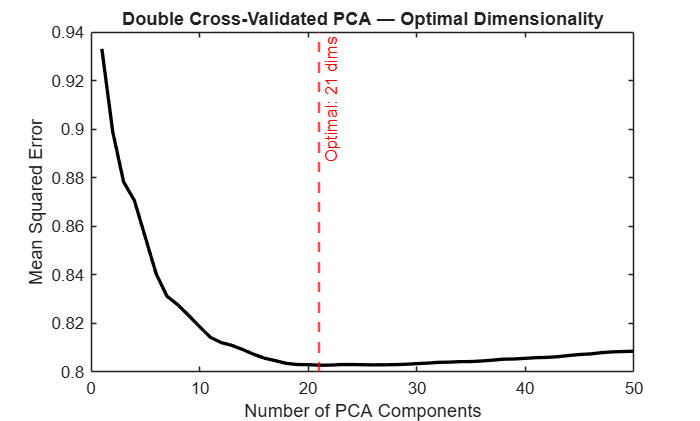

Optimal dimensionality: 21


[firingRateMatrix, conditionLabels] = buildFiringRateMatrix(R);
[optimalDims, pcaData] = crossValidatePCA(firingRateMatrix, 50);

We employed a double cross validation approach in which we split both the trials and neurons to find the optimal number of dimensions that explain the variance of our data. Upon sweeping to 50 dimensions, we found that approximately 21 dimensions minimized the mean squared error, which is the dimensionality we used in our nonlinear dimensionality reduction visualizations. This is done for the movement period of the trials. This is a necessary step to prevent tears and twists and helps deal with the "curse of dimensionality." In such high dimension space, pairwise distances aren't reliable as nearly everything is equidistant. Running PCA on the data first, compresses it into meaningful dimensions.

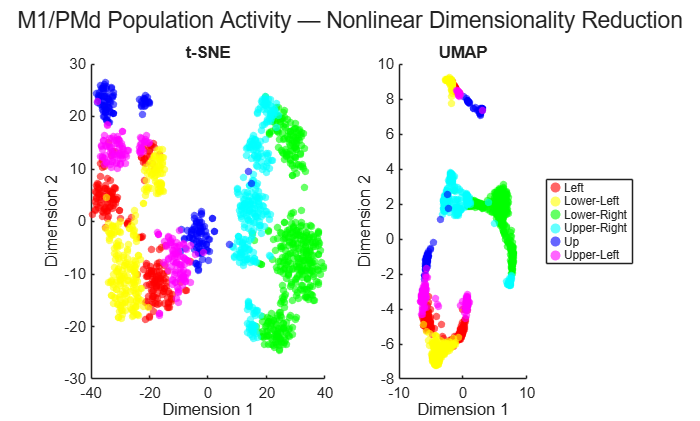

Pairwise distance matrix correlation (t-SNE vs UMAP): r = 0.496


% Plot
plotNLDimReduction(pcaData, conditionLabels);

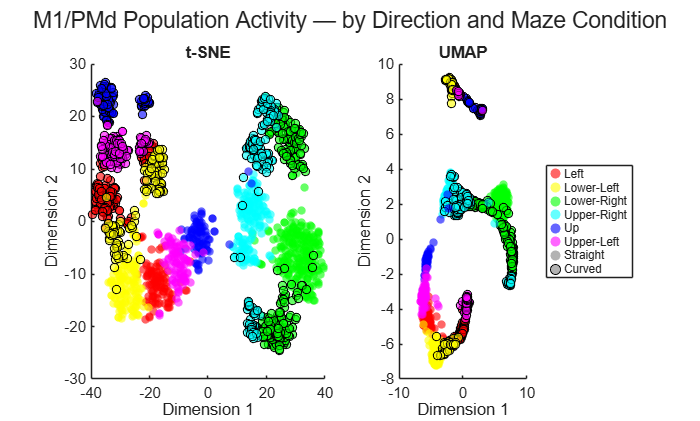

Pairwise distance matrix correlation (t-SNE vs UMAP, by-condition): r = 0.496
Straight trials: 788, Curved trials: 769


% Plot by Condition
isStraight = [R.mazeCategory] == 'noBarriers';
isStraight = isStraight(:);
[tSNEEmbedding, umapEmbedding] = plotNLDimReductionByCondition(pcaData, conditionLabels, isStraight);

Both t-SNE and UMAP separate our defined clusters, confirming that direction is a relevant axis of variance during movement. Furthermore, adjacent directions do appear to cluster in similar spaces in both methods. However, it is important to note that the geometry of each embedding should be interpreted with caution. One reason for this is that target directions are not uniformly sampled around the circle and the number of trials per direction varies a sizable amount(168 - 440). Because nonlinear dimensionality reduction can be sensitive to local neighborhood densities, the geometry of the embeddings(size and shape) may partially reflect uneven sampling rather than real neural structure. Splitting the visualization further by task condition(barrier vs no barrier) reveals that the type of reach is another feature organized in the low d manifold. This suggests that population activity also encodes reach type, something that may not be visible in individual neuron level analysis. Additional analysis: We computed the pairwise distances for every pair of trials in the embedding and then correlated the two vectors, asking the question: for each pair of trials, do t-SNE and UMAP agree on how far they are. We got r = 0.804, which suggests that the two methods actually agree a fair amount in their visualizations.

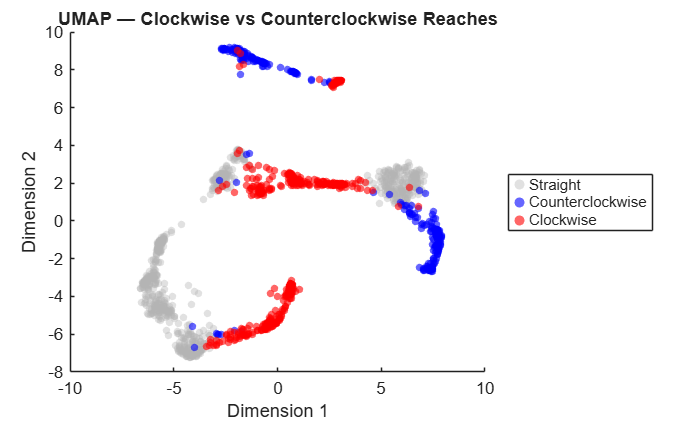

CW: 476, CCW: 293, Straight: 788


% Separate clockwise vs. counterclockwise
curveDir = getCurveDirection(R);
plotUMAPByCurve(umapEmbedding, curveDir);

Taking a look at whether or not the rings that emerged from the UMAP embedding were a result of counterclockwise vs clockwise reaches. We performed an additional visualization to separate the two. It appears that the rings are a product of curve direction as this feature too is well separable in the manifold. It then seems that the population activity is encoding another relevant behavioral feature in this low dimensional representation, which manifest as circular/curved patterns, similar to the movements themselves. 

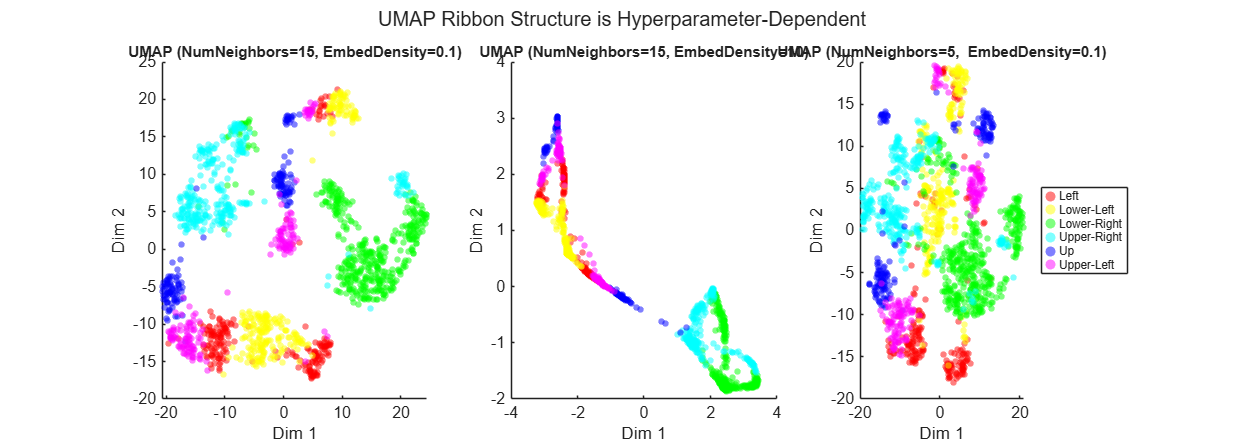

% Hyperparameter Examination

% UMAP
figure('Position', [100 100 1400 500]);

rng(1);
umap1 = umap(pcaData, 'NumNeighbors', 15, 'EmbeddingDensity', 0.1);
rng(1);
umap2 = umap(pcaData, 'NumNeighbors', 15, 'EmbeddingDensity', 10);
rng(1);
umap3 = umap(pcaData, 'NumNeighbors', 5,  'EmbeddingDensity', 0.1);

umapEmbeddings = {umap1, umap2, umap3};
umapTitles = {'UMAP (NumNeighbors=15, EmbedDensity=0.1)', ...
    'UMAP (NumNeighbors=15, EmbedDensity=10)', ...
    'UMAP (NumNeighbors=5,  EmbedDensity=0.1)'};

colors = hsv(6);
dirLabels = {'Left','Lower-Left','Lower-Right','Upper-Right','Up','Upper-Left'};
uniqueConditions = unique(conditionLabels);

for e = 1:3
    subplot(1, 3, e);
    hold on;
    for c = 1:6
        mask = conditionLabels == uniqueConditions(c);
        scatter(umapEmbeddings{e}(mask,1), umapEmbeddings{e}(mask,2), ...
            15, colors(c,:), 'filled', 'MarkerFaceAlpha', 0.5, ...
            'DisplayName', dirLabels{c});
    end
    title(umapTitles{e}, 'FontSize', 9);
    xlabel('Dim 1');
    ylabel('Dim 2');
    if e == 3
        legend('Location', 'eastoutside', 'FontSize', 7);
    end
    hold off;
end
sgtitle('UMAP Ribbon Structure is Hyperparameter-Dependent', 'FontSize', 12);

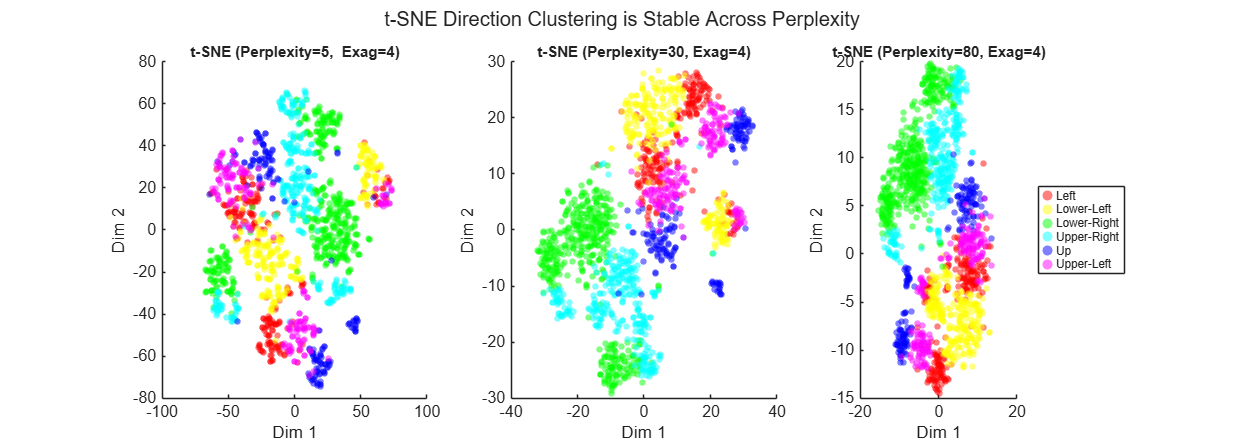



% t-SNE
figure('Position', [100 100 1400 500]);

rng(1);
tsne1 = tsne(pcaData, 'NumDimensions', 2, 'Perplexity', 5,  'Standardize', true, 'Exaggeration', 4);
rng(1);
tsne2 = tsne(pcaData, 'NumDimensions', 2, 'Perplexity', 30, 'Standardize', true, 'Exaggeration', 4);
rng(1);
tsne3 = tsne(pcaData, 'NumDimensions', 2, 'Perplexity', 80, 'Standardize', true, 'Exaggeration', 4);

tsneEmbeddings = {tsne1, tsne2, tsne3};
tsneTitles = {'t-SNE (Perplexity=5,  Exag=4)', ...
    't-SNE (Perplexity=30, Exag=4)', ...
    't-SNE (Perplexity=80, Exag=4)'};

for e = 1:3
    subplot(1, 3, e);
    hold on;
    for c = 1:6
        mask = conditionLabels == uniqueConditions(c);
        scatter(tsneEmbeddings{e}(mask,1), tsneEmbeddings{e}(mask,2), ...
            15, colors(c,:), 'filled', 'MarkerFaceAlpha', 0.5, ...
            'DisplayName', dirLabels{c});
    end
    title(tsneTitles{e}, 'FontSize', 9);
    xlabel('Dim 1');
    ylabel('Dim 2');
    if e == 3
        legend('Location', 'eastoutside', 'FontSize', 7);
    end
    hold off;
end
sgtitle('t-SNE Direction Clustering is Stable Across Perplexity', 'FontSize', 12);

To test how dependent the global structure of these embeddings are on the hyperparameters, we varied perplexity for t-SNE and NumNeighbors and embedding density for UMAP. For t-SNE, perplexity controls the number of neighbors each point considers, a lower perplexity focuses on local structure, whereas a higher perplexity incorporates a broader neighborhood. Across the 3 perplexity values we tested, t-SNE produces similar looking embeddings, defined by discrete and well separated direction clusters. For UMAP, the hyperparameters we adjusted were NumNeighbors, which is similar to perplexity and embedding density, which controls how tight points are packed in the manifold. With the default settings, we saw the embedding form continuous thin structures. Increasing embedding density further compacts the visualization further. On the other hand, decreasing the number of neighbors to 5 produces a more discrete clustering as we saw in t-SNE. This reveals that the shapes we saw earlier for UMAP were largely dependent on the hyperparameters, not necessarily features of our data. Taking this together, the directional cluster remains consistent across both methods and the various parameters we tested. Trials that were towards the same reach direction tended to group together. However, the specific differences in geometry should be treated with caution, as you can achieve relatively similar arrangements in both methods.

## Decoder: Ridge Regression vs. Random Forest

We will decode position/velocity over time from M1 neural data using 1) ridge regression and 2) random forest regression, comparing cross validated performance and their resulting reach trajectories.

decoderModel = trainDecoder(R, 5);

Ridge: best lambda: 494.1713 , CV R²: Vx=0.681, Vy=0.470
Random Forest — R²: Vx=0.685, Vy=0.488


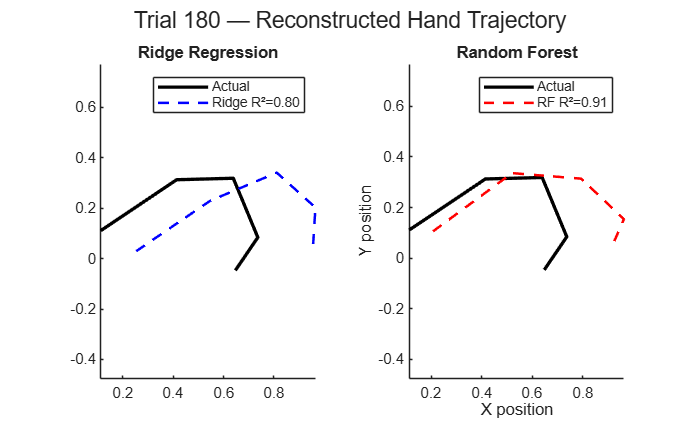

plotDecodedTrajectory(decoderModel, R, 180);

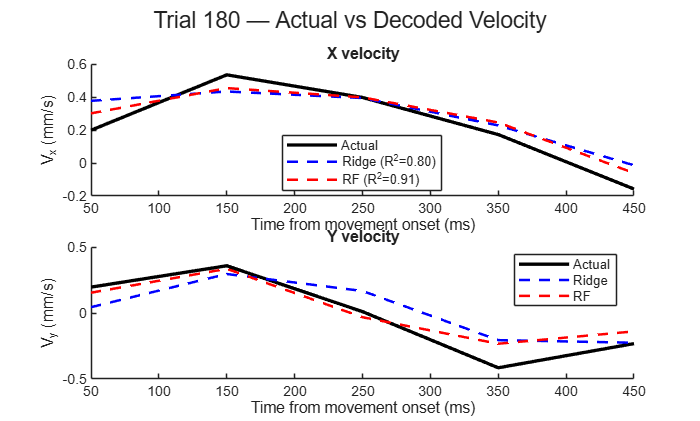

plotDecodedVelocity(decoderModel, R, 180);

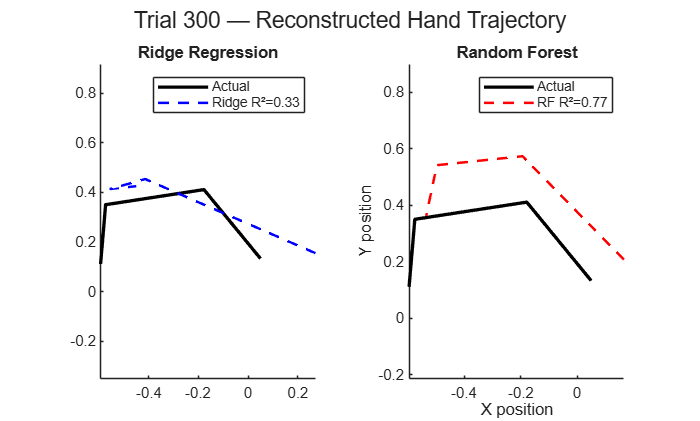

plotDecodedTrajectory(decoderModel, R, 300);

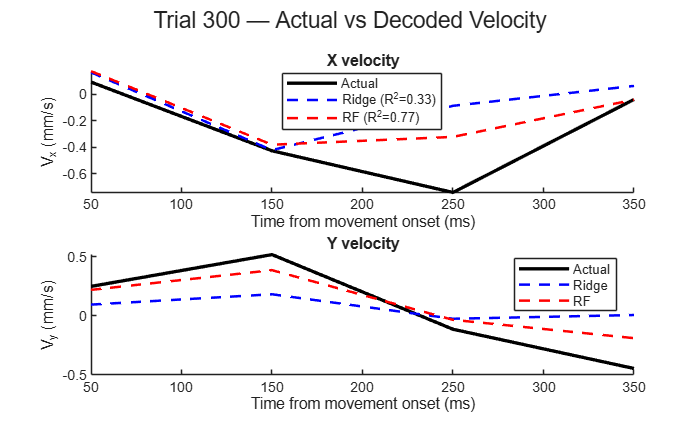

plotDecodedVelocity(decoderModel, R, 300)

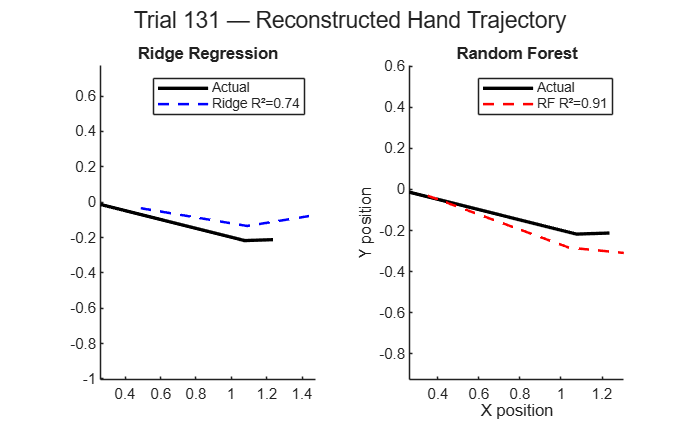

plotDecodedTrajectory(decoderModel, R, 131);

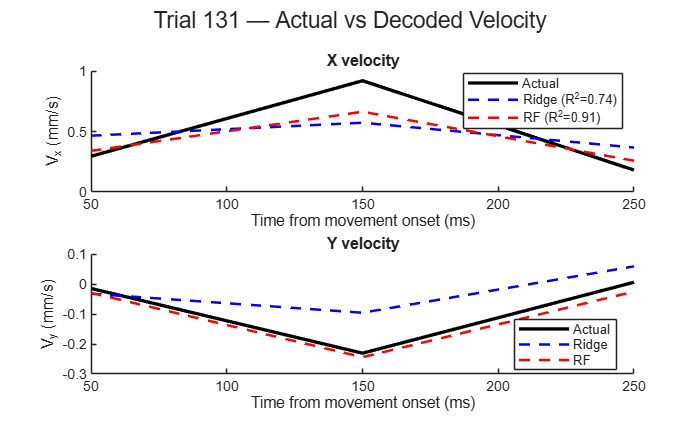

plotDecodedVelocity(decoderModel, R, 131);

It appears that the nonlinear decoder(random forest) and linear decoder(ridge regression) perform similarly well, as their cross validated R^2's are nearly identical. This lack of major difference seems to suggest that the relationship between firing rates and hand velocity is approximately linear. The difference between aggregate performance is small enough that it does not provide strong evidence of a real nonlinear relationship. On the individual trials, random forest does seem to reconstruct trajectories more faithfully, but given that we only plotted 3 trials, this is more likely just trial to trial variability. There does seem to be a tradeoff. A linear regression, like ridge regression, is more interpretable than the random forest approach, which is sort of like a black box. Random forest may perform better in some cases, but it's difficult to ask questions of. With a linear regression, we can directly ask what neurons contribute and how much, something that's important when we want to understand the motor cortex not just predict movement.

## Classifer

We will classify curved vs. straight reaches based on neural data from the delay and movement period separately using SVM and logistic regression to assess when kinematic information is encoded in M1. We will assess the significance of our classifier using a Monte Carlo  shuffle test, where we shuffle curved vs straight trial labels 1000 times to generate a null distribution and compute a p-value for each method/time-window combination.

Firing rates computed.

Straight (No Barriers):
  Value    Count   Percent
      1      104     13.20%
      2      133     16.88%
      3      221     28.05%
      4      152     19.29%
      5       83     10.53%
      6       95     12.06%

Curved (Barriers):
  Value    Count   Percent
      1      109     14.17%
      2      119     15.47%
      3      219     28.48%
      4      146     18.99%
      5       85     11.05%
      6       91     11.83%

SVM (RBF) | Delay Period | Straight (No Barriers)
Observed accuracy = 0.942
p-value = 0.0010

Logistic Regression | Delay Period | Straight (No Barriers)
Observed accuracy = 0.939
p-value = 0.0010

SVM (RBF) | Movement Period | Straight (No Barriers)
Observed accuracy = 0.980
p-value = 0.0010



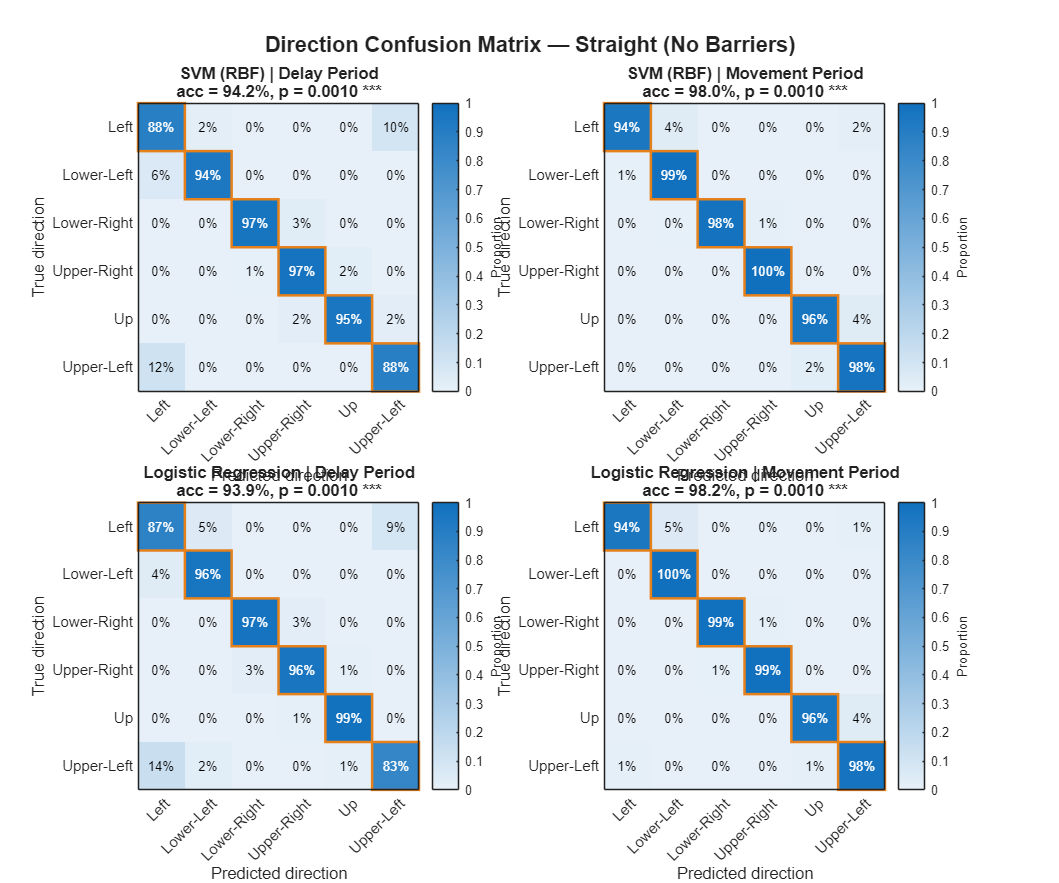

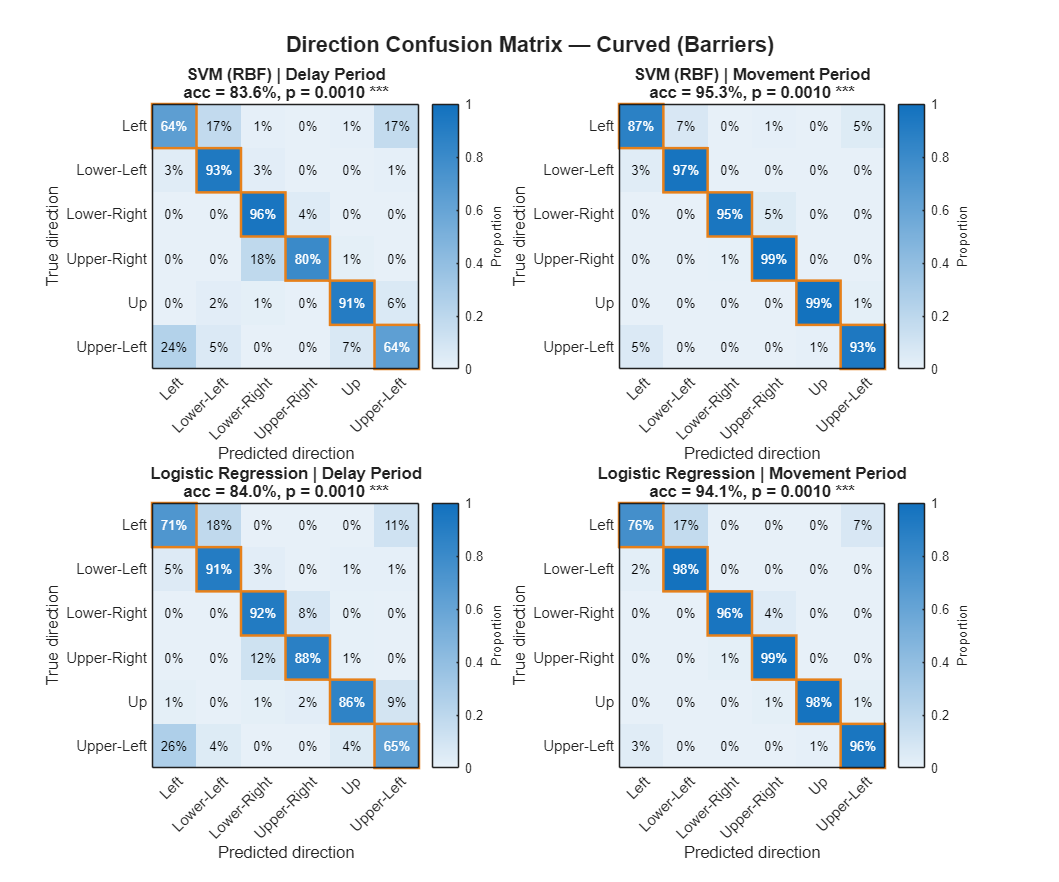

ans = struct with fields:
     obs_acc: [2×2×2 double]
    perm_acc: [2×2×2×1000 double]
    p_values: [2×2×2 double]
        pred: {2×2×2 cell}
    true_lab: {2×2×2 cell}
      params: [1×1 struct]


classifier(R)

In both the curved and straight trajectories, the classifiers performed better when trained on the movement period than on the delay period. This suggests that neural activity in the movement period more richly encodes directional information than in the delay period. In addition, both the SVM classifer with an RBF kernel and the logisitc regression performed well. This might suggest that the directions are linearly separable in neural space, as both a linear and nonlinear classifier could successfully decode direction. Also, between the curved and straight trajectories, the classifier performed well. This suggests that even though the curved trajectory might have been a more complex behavior, direction is still separable. 